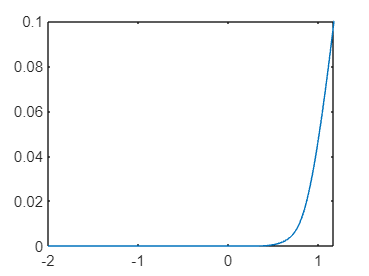

load("matlab.mat");
shulty=cell2mat(data_1(8:1007,2:3));
nolight=cell2mat(data_nolight(8:1007,2:3));
weaklight=cell2mat(data_weaklight(8:1007,2:3));
stronglight=cell2mat(data_stronglight(8:1007,2:3));
plot(nolight(:,1),nolight(:,2));

%二极管的I-V曲线
V=shulty(:,1);
I=shulty(:,2);
plot(V,I);
title("肖特基二极管的I-V曲线");
xlabel("正向电压/V");
ylabel("正向电流/A");


%整流比
rect_ratio=I(700)./I(300);

%开启电压提取
for i=1:length(I)-1
    d_I(i)=I(i+1)-I(i);
end
for i=1:length(d_I)-1
    dd_I(i)=d_I(i+1)-d_I(i);
end

%开启电阻
min=525;
max=620;
lin_I=I(min:max);
lin_V=V(min:max);
plot(lin_I,lin_V);
title("肖特基二极管的V-I曲线");
ylabel("正向电压/V");
xlabel("正向电流/A");

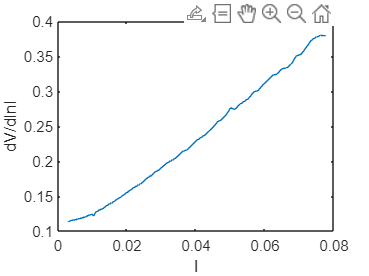

%理想因子
min=380;
max=460;
ln_I=log(abs(I));
for i=1:length(I)-1
D(i)=(V(i+1)-V(i))./(ln_I(i+1)-ln_I(i));
end
plot(I(min:max),D(min:max));
xlabel("I");
ylabel("dV/dlnI");

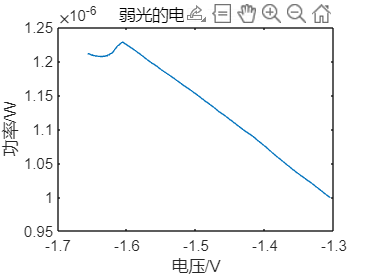

%最大电压、最大电流
min=50;
max=100;
P=abs(I(min:max).*V(min:max));
plot(V(min:max),P);
xlabel("电压/V");
ylabel("功率/W");
title("弱光的电压-功率曲线");

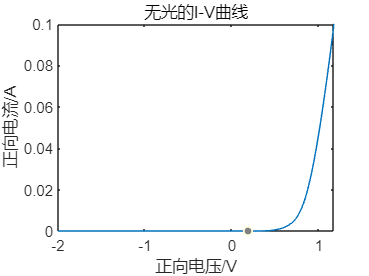

%无光的I-V曲线
[V,Index]=sort(nolight(:,1));
I=nolight(Index,2);
plot(V,I);
title("无光的I-V曲线");
xlabel("正向电压/V");
ylabel("正向电流/A");

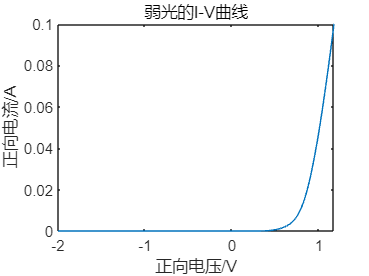

%弱光的I-V曲线
[V,Index]=sort(weaklight(:,1));
I=weaklight(Index,2);
plot(V,I);
title("弱光的I-V曲线");
xlabel("正向电压/V");
ylabel("正向电流/A");

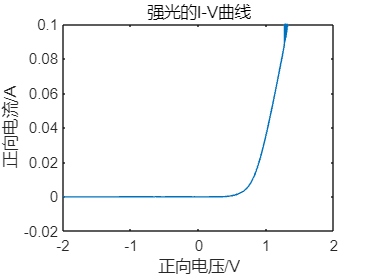

%强光的I-V曲线
[V,Index]=sort(stronglight(:,1));
I=stronglight(Index,2);
plot(V,I);
title("强光的I-V曲线");
xlabel("正向电压/V");
ylabel("正向电流/A");